%select teh top 200 columns and run the analysis on them

% figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
allsubj={7349, 7356, 7361, 7375, 7376,...
         7383, 7402, 7403, 7404,...
         7405, 7408, 7414, 7415,...
         7425, 7426, 7433, 7434,...
         7435, 7443, 7444, 7445,...
         7448, 7449, 7452, 7453,...
         7454, 7455, 7456, 7457,...
         7468, 7469, 7482, 7484, 7485}; %34subj 7349 output was too big-->not safed and need to rerun, and 7356 has no good orientation was not run at all.32 is visualized now
subplotsize=[8 4];
% disp('This is the distribution of the indiviudal T value(across columns) for the three contrast')
for subj=allsubj%{7414,7482,7484,7485}
    roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
    columnartsfile=[roipath num2str(subj{:}) '\functionalmasks\interimdata_rwls.mat'];
    if exist(columnartsfile,"file")
%         disp(subj)
        disp([num2str(subj{:}) ' subject columnar info r'])
        plotidx=plotidx+1;
        [stat,columndistribution,layerwisestat]=BK_layer_sampling_pain_study_pipeline(subj);
        allsubjlayer{plotidx}=layerwisestat;
%         subplot(subplotsize(1), subplotsize(2), plotidx);
%         hcogn=histogram(stat.T(:,:,1),'BinLimits',[-5,5],'FaceColor', 'blue');
%         hold on
%         hpain=histogram(stat.T(:,:,2),'BinLimits',[-5,5],'FaceColor', 'red');
%         hconj=histogram(stat.T(:,:,3),'BinLimits',[-5,5],'FaceColor', 'green');
%         xline(1,'-','LineWidth', 1.5,'Color', 'blue');
%         xline(0,'-','LineWidth', 1.5,'Color', 'red');
%         title(num2str(subj{:}))
%         if plotidx==1
%             legend('Cognitive act (Blue)', 'Pain act (Red)','Conjuction act (Blue)','t>1', 'Location', 'northwestoutside');
%         end
%         
%         hold off
    else
        disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    end

end

7349 subject has  no sampled cluster
7356 subject has  no sampled cluster


7361 subject columnar info r


Time for one subject to process:Elapsed time is 17.337028 seconds.


7375 subject columnar info r


Time for one subject to process:Elapsed time is 17.640892 seconds.


7376 subject columnar info r


Time for one subject to process:Elapsed time is 19.146197 seconds.


7383 subject columnar info r


Time for one subject to process:Elapsed time is 20.374936 seconds.


7402 subject columnar info r


Time for one subject to process:Elapsed time is 21.476859 seconds.


7403 subject columnar info r


Time for one subject to process:Elapsed time is 18.807554 seconds.


7404 subject columnar info r


Time for one subject to process:Elapsed time is 17.919691 seconds.


7405 subject columnar info r


Time for one subject to process:Elapsed time is 18.873468 seconds.


7408 subject columnar info r


Time for one subject to process:Elapsed time is 19.299604 seconds.


7414 subject columnar info r


Time for one subject to process:Elapsed time is 18.795267 seconds.


7415 subject columnar info r


Time for one subject to process:Elapsed time is 20.907868 seconds.


7425 subject columnar info r


Time for one subject to process:Elapsed time is 18.204386 seconds.


7426 subject columnar info r


Time for one subject to process:Elapsed time is 18.643943 seconds.


7433 subject columnar info r


Time for one subject to process:Elapsed time is 19.822614 seconds.


7434 subject columnar info r


Time for one subject to process:Elapsed time is 18.082343 seconds.


7435 subject columnar info r


Time for one subject to process:Elapsed time is 19.255855 seconds.


7443 subject columnar info r


Time for one subject to process:Elapsed time is 20.559821 seconds.


7444 subject columnar info r


Time for one subject to process:Elapsed time is 19.455678 seconds.


7445 subject columnar info r


Time for one subject to process:Elapsed time is 18.685355 seconds.


7448 subject columnar info r


Time for one subject to process:Elapsed time is 16.402370 seconds.


7449 subject columnar info r


Time for one subject to process:Elapsed time is 18.258247 seconds.


7452 subject columnar info r


Time for one subject to process:Elapsed time is 18.275159 seconds.


7453 subject columnar info r


Time for one subject to process:Elapsed time is 20.391235 seconds.


7454 subject columnar info r


Time for one subject to process:Elapsed time is 18.329048 seconds.


7455 subject columnar info r


Time for one subject to process:Elapsed time is 18.353758 seconds.


7456 subject columnar info r


Time for one subject to process:Elapsed time is 18.894664 seconds.


7457 subject columnar info r


Time for one subject to process:Elapsed time is 18.519295 seconds.


7468 subject columnar info r


Time for one subject to process:Elapsed time is 17.628236 seconds.


7469 subject columnar info r


Time for one subject to process:Elapsed time is 19.088422 seconds.


7482 subject columnar info r


Time for one subject to process:Elapsed time is 19.015733 seconds.


7484 subject columnar info r


Time for one subject to process:Elapsed time is 18.790447 seconds.


7485 subject columnar info r


Time for one subject to process:Elapsed time is 17.848598 seconds.


maki=squeeze(allsubjlayer{2}.beta(:,:,:));
maki(:,2)

ans =   -16.9972
  -19.9286
  -22.7618
  -25.0967
  -26.8058
  -28.5020
  -29.9355
  -31.0517
  -31.9142
  -32.2962


size(allsubjlayer{2}.beta(:,:,:))

ans =     20     1     2



%visualize hte ß distribution as a function of layers
% allsubjlayerresp=nan
for subj=1:length(allsubjlayer)
    allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:)),2)';
    allsubjlayerresp_T(subj,:)=mean(squeeze(allsubjlayer{subj}.T(:,:,:)),2)';
end


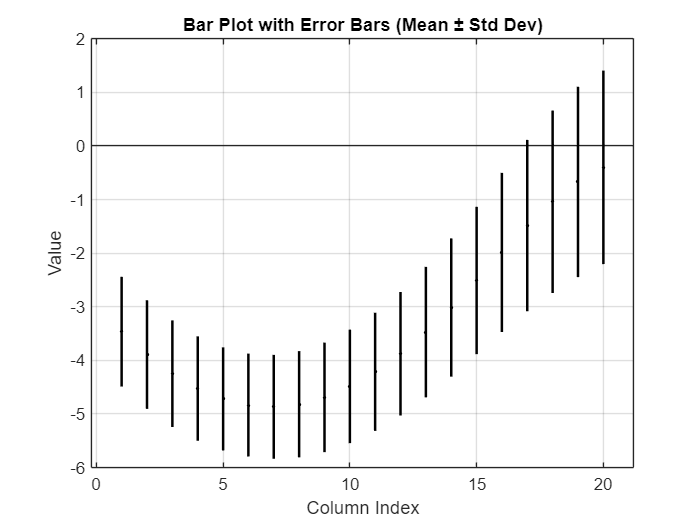



% Example matrix of size 10x20
data = allsubjlayerresp_T; % Random data for demonstration

% Calculate column-wise mean and standard deviation
columnMeans = mean(data, 1); % Mean of each column
columnStdDevs = std(data, 0, 1); % Standard deviation of each column

% Create the bar plot
figure;
bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
hold on;

% Add error bars
errorbar(1:length(columnMeans), columnMeans, columnStdDevs, ...
    'k.', 'LineWidth', 1.5); % Error bars in black

% Customize the plot
xlabel('Column Index');
ylabel('Value');
title('Bar Plot with Error Bars (Mean ± Std Dev)');
grid on;
hold off;

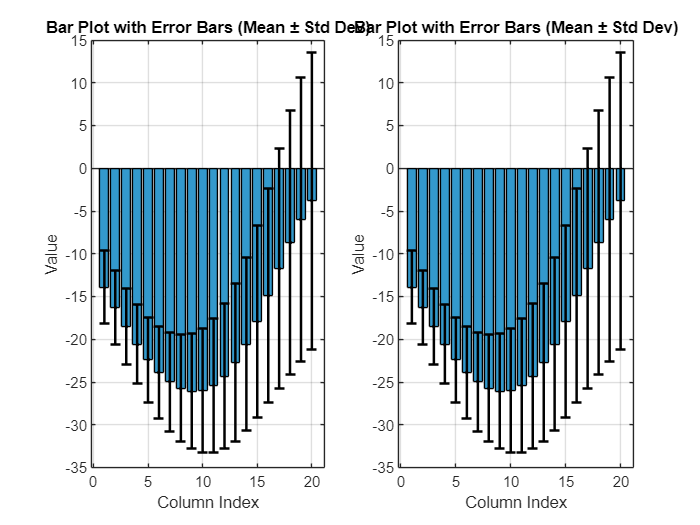

Error using subplot (line 319)
Index exceeds number of subplots.

% figure;
% plotidx=0;
% for subj=1:length(allsubjlayer)
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:)),2)';
%     allsubjlayerresp_T(subj,:)=mean(squeeze(allsubjlayer{subj}.T(:,:,:)),2)';
%     plotidx=plotidx+1;
% % Example matrix of size 10x20
%     data = allsubjlayerresp; % Random data for demonstration
%     
%     % Calculate column-wise mean and standard deviation
%     columnMeans = mean(data, 1); % Mean of each column
%     columnStdDevs = std(data, 0, 1); % Standard deviation of each column
%     
%     % Create the bar plot
%     subplot(1,2,plotidx)
%     bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
%     hold on;
%     
%     % Add error bars
%     errorbar(1:length(columnMeans), columnMeans, columnStdDevs, ...
%         'k.', 'LineWidth', 1.5); % Error bars in black
%     
%     % Customize the plot
%     xlabel('Column Index');
%     ylabel('Value');
%     title('Bar Plot with Error Bars (Mean ± Std Dev)');
%     grid on;
%     hold off;
% end

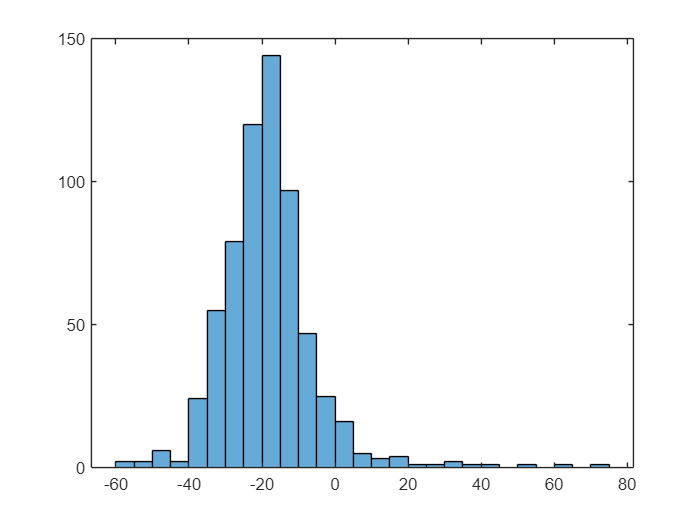


histogram(HC_onpain)

%     {'pain_high_cogn_high_pain'   }
%     {'pain_high_cogn_low_pain'    }
%     {'pain_low_cogn_high_pain'    }
%     {'pain_low_cogn_low_pain'     }
for subj=1:length(allsubjlayer)
%     HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1,1)-allsubjlayer{subj}.beta(:,1,2);
%     LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,3,1)-allsubjlayer{subj}.beta(:,1,4);

    HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1);
    LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,2);
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:,1)),2)';    
end

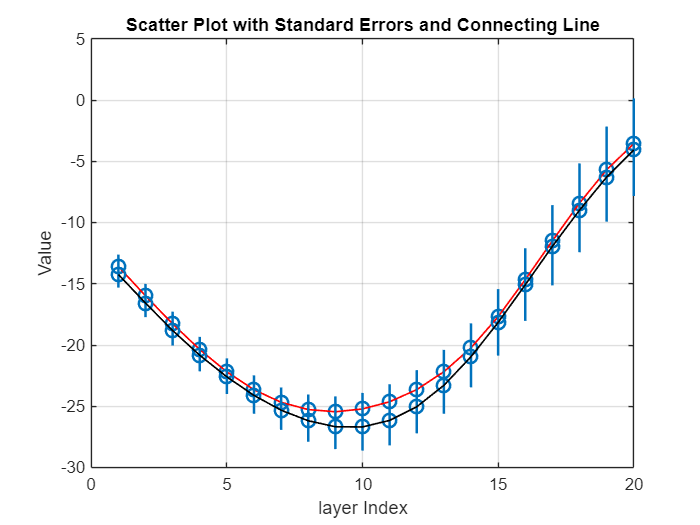

% Example matrix of size 10x20
% data = HC_onpain; % Random data for demonstration
figure;
alldata={HC_onpain, LC_onpain};
for dataidx=1:2
    % Calculate column-wise mean and standard error
    data=alldata{dataidx};
    columnMeans = mean(data, 1); % Mean of each column
    columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
    
    % Create the scatter plot
    
    errorbar(1:20, columnMeans, columnStdErrors, ...
        'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
    hold on;
    
    % Connect the points with a line
    if dataidx==1
        plot(1:20, columnMeans, '-r', 'LineWidth', 1);
    else
        plot(1:20, columnMeans, '-k', 'LineWidth', 1);
    end
    
    % Customize the plot
    xlabel('layer Index');
    ylabel('Value');
    title('Scatter Plot with Standard Errors and Connecting Line');
    grid on;
end
hold off;